**3. Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observados nos 4 lançamentos.**

**(a) **Estime por simulação a função massa de probabilidade pX(x) da variável aleatória X.

experiencias_a = rand(4, 1e6);
sucessos_a = experiencias_a < 0.5;
quantidade_coroas = sum(sucessos_a);
casosFavoraveis_0 = sum(quantidade_coroas == 0);
casosFavoraveis_1 = sum(quantidade_coroas == 1);
casosFavoraveis_2 = sum(quantidade_coroas == 2);
casosFavoraveis_3 = sum(quantidade_coroas == 3);
casosFavoraveis_4 = sum(quantidade_coroas == 4);

prob_0 = casosFavoraveis_0/1e6

prob_0 = 0.0626

prob_1 = casosFavoraveis_1/1e6

prob_1 = 0.2498

prob_2 = casosFavoraveis_2/1e6

prob_2 = 0.3757

prob_3 = casosFavoraveis_3/1e6

prob_3 = 0.2498

prob_4 = casosFavoraveis_4/1e6

prob_4 = 0.0622

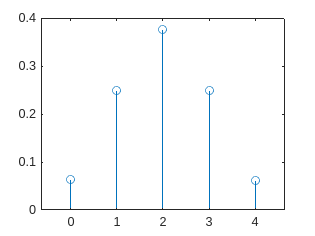


x = 0:4;
prob_x = [prob_0, prob_1, prob_2, prob_3, prob_4];
stem(x, prob_x)

**(b)** Estime o valor esperado, a variância e o desvio padrão de X com base em pX (x).

valor_esperado = sum(prob_x.*x)

valor_esperado = 2.0001

M_xx = sum(prob_x.*x.^(2))

M_xx = 5.0016

var_x = M_xx - valor_esperado^2

var_x = 1.0010

desvio_padrao = sqrt(var_x)

desvio_padrao = 1.0005

**(c)** Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teórica da respetiva função de probabilidade.

Resposta:

Distribuição discreta;

Fx = Px(0) + Px(1) + Px(2) + Px(3) + Px(4) = 0.06 + 0.25 + 0.38 + 0.25 + 0.06

**(d)** Calcule os valores teóricos da função massa de probabilidade de X e compare-os com os valores estimados por simulação obtidos em (a).

P(0) = C(4,0)/(2^4) = 1/16 = 0.0625

P(1) = C(4,1)/(2^4) = 4/16 = 1/4 = 0.25

P(2) = C(4,2)/(2^4) = 6/16 = 0.375

P(3) = C(4,3)/(2^4) = 4/16 = 1/4 = 0.25

P(4) = C(4,4)/(2^4) = 1/16 = 0.0625

Conclusão: Os valores são bastantes similares aos calculados por simulação

**(e) **Calcule os valores teóricos de E[x] e de Var(X) e compare-os com os valores obtidos em (b).

E[x] = 0*P(0) + 1*P(1) + 2*P(2) + 3*P(3) + 4*P(4) = 2

E[x^2] = 0^2*P(0) + 1^2*P(1) + 2^2*P(2) + 3^2*P(3) + 4^2*P(4) = 5

Var(X) = E[x^2] - E[x]^2 = 5 - 2^2 = 1

Conclusão: Os valores são bastantes similares aos calculados por simulação

**(f)** Com base nos valores teóricos da função massa de probabilidade desta distribuição, calcule:

**i.** a probabilidade de obter pelo menos 2 coroas;

P(pelo menos 2) = P(0) + P(1) + P(2) = 0.0625 + 0.25 + 0.375 = 0.6875

**ii.** a probabilidade de obter até 1 coroa;

P(até 1 coroa) = P(0) + P(1) = 0.0625 + 0.25 = 0.3125

**iii.** a probabilidade de obter entre 1 e 3 coroas.

P(entre 1 e 3 coroas) = P(1) + P(2) + P(3) = 0.875